%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


reps = 10;

Q_orig = 1e6;
Q = Q_orig / heterodyning_ratio;

band_width = f_a / Q % or f_a_original / Q_orig

band_width = 483.5590


T = 10e-3;

tau = 0.0143e-3;

w_mult = 3.5;
f_0s = linspace(f_a - w_mult*band_width, f_a + w_mult*band_width, 24);
L_f0s = length(f_0s);

dynamic_powers = zeros(reps, L_f0s);
static_powers  = zeros(reps, L_f0s);

start_secs = 0.0015;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

done = 0;
num_runs = reps * L_f0s

num_runs = 200

tic

for l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_orig);
    noise_power = calculate_noise_power(f_sampling, T);
    noise = generate_thermal_noise(t, noise_power);
    p_s = bandpower(signal)
    p_n = bandpower(noise)
    
%     noise_resonated  = resonator_2(noise, f_0s(1),   band_width, f_sampling);
%     noise_resonated2 = resonator_2(noise, f_0s(end), band_width, f_sampling);
%     power_just_noise  = bandpower(noise_resonated (start:end))
%     power_just_noise2 = bandpower(noise_resonated2(start:end))
    
    parfor i = 1 : L_f0s
        f_0 = f_0s(i);

        limiting_band = [f_0-band_width, f_0+band_width];

        [f_iwave, signal_dynamic] = do_iwave_and_resonator(t, noise, signal, f_0, band_width, f_sampling, limiting_band, tau);
        signal_static = resonator_2(noise + signal, f_0, band_width, f_sampling);

        dynamic_powers(l, i) = bandpower(signal_dynamic(start:end));
        static_powers (l, i) = bandpower(signal_static (start:end));
    end
    done = done + L_f0s;
    frac_done = done/num_runs;
    timer_elapsed = toc;
    time_total = timer_elapsed / frac_done;
    time_remaining = time_total - timer_elapsed;
    fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
    
end

p_s = 1.4286e-20

p_n = 1.5832e-17

done 10%, 1 min gone, 10 min rem


p_s = 1.4286e-20

p_n = 1.5844e-17

done 20%, 2 min gone, 8 min rem


p_s = 1.4286e-20

p_n = 1.5835e-17

done 30%, 3 min gone, 7 min rem


p_s = 1.4286e-20

p_n = 1.5848e-17

done 40%, 4 min gone, 6 min rem


p_s = 1.4286e-20

p_n = 1.5826e-17

done 50%, 5 min gone, 5 min rem


p_s = 1.4286e-20

p_n = 1.5849e-17

done 60%, 6 min gone, 4 min rem


p_s = 1.4286e-20

p_n = 1.5845e-17

done 70%, 7 min gone, 3 min rem


p_s = 1.4286e-20

p_n = 1.5838e-17

done 80%, 8 min gone, 2 min rem


p_s = 1.4286e-20

p_n = 1.5833e-17

done 90%, 9 min gone, 1 min rem


p_s = 1.4286e-20

p_n = 1.5881e-17

done 100%, 10 min gone, 0 min rem


dynamic_power = mean(dynamic_powers, 1);
static_power  = mean(static_powers,  1);
dynamic_power_err = std(dynamic_powers, 1);
static_power_err  = std(static_powers,  1);

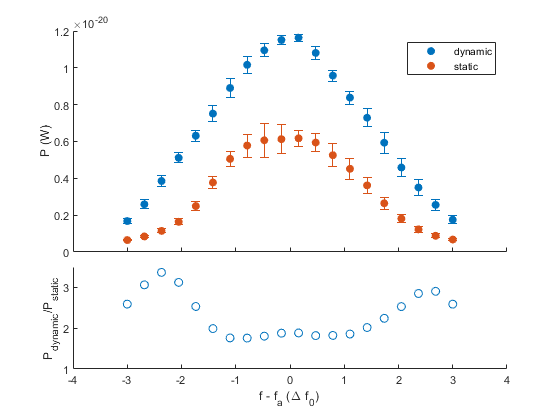

figure
tiledlayout(3,1, 'TileSpacing','tight')

nexttile([2, 1])
c = colororder;
df = f_a / Q;
scatter((f_0s-f_a)/df, dynamic_power, [], c(1,:), 'filled')
hold on
scatter((f_0s-f_a)/df, static_power,  [], c(2,:), 'filled')
errorbar((f_0s-f_a)/df, dynamic_power, dynamic_power_err/2, 'color',c(1,:), 'LineStyle','none', 'HandleVisibility',"off")
errorbar((f_0s-f_a)/df, static_power,  static_power_err/2,  'color',c(2,:), 'LineStyle','none', 'HandleVisibility',"off")
legend('dynamic', 'static')
ylabel('P (W)')
xticklabels([])
xlim([-4 4])

nexttile
scatter((f_0s-f_a)/df, dynamic_power./static_power)
%y_lim = ylim();
%ylim([0, y_lim(2)])
ylabel('P_{dynamic}/P_{static}')
xlim([-4 4])
ylim([1 3.5])

xlabel('f - f_a (\Delta f_0)')